# Dekompozycja SVD - kompresja obrazów

Wczytywanie leny

clear all
X=imread('lena512.bmp');
% Xg=double(rgb2gray(X));

dekompozycja wartosci osobliwych svd

[U,S,V] = svd(single(X));
i1_post = U*S*V';

efekt odtworzenia:

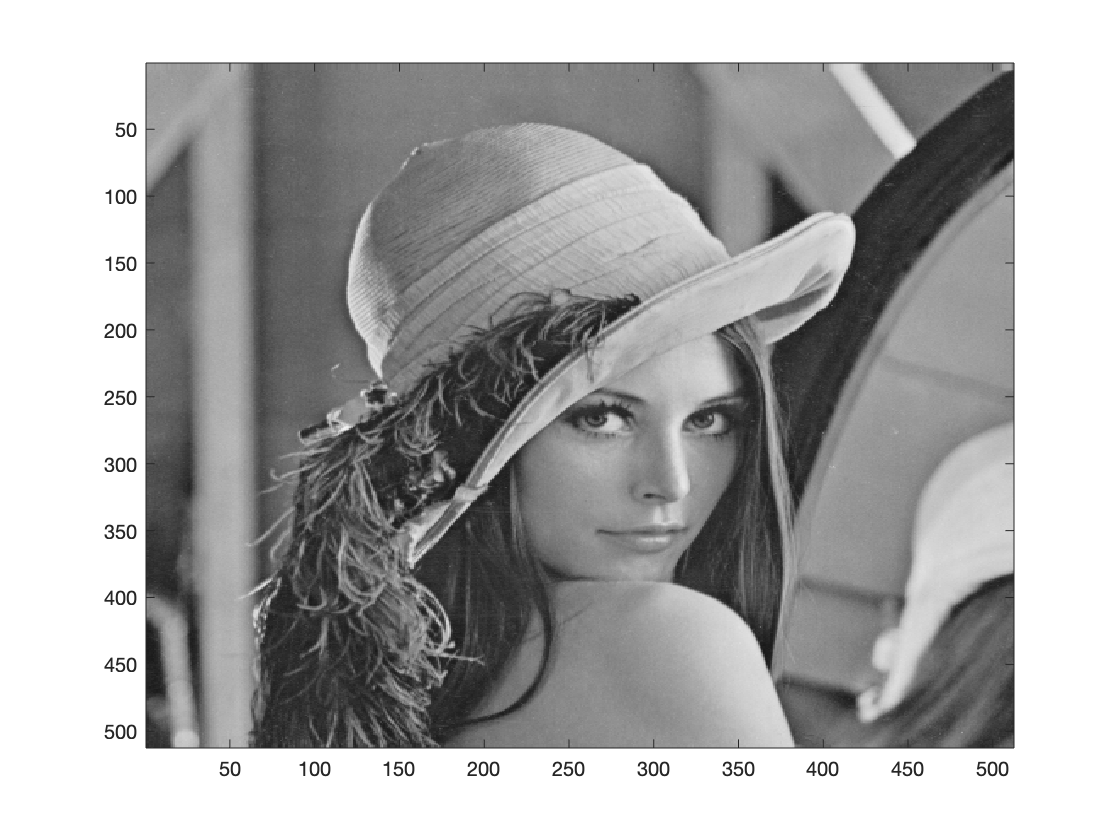

image(i1_post)
colormap gray

poziom podobienstwa:

ssim(i1_post,single(X))

ans = single
1.0000

## Odtwarzanie wykorzystujac czesc informacji

compressy = {Compress(U,S,V,50), Compress(U,S,V,25), ...
    Compress(U,S,V,10), Compress(U,S,V,5), Compress(U,S,V,1)};

poziom kompresji dla pierwszych 50:

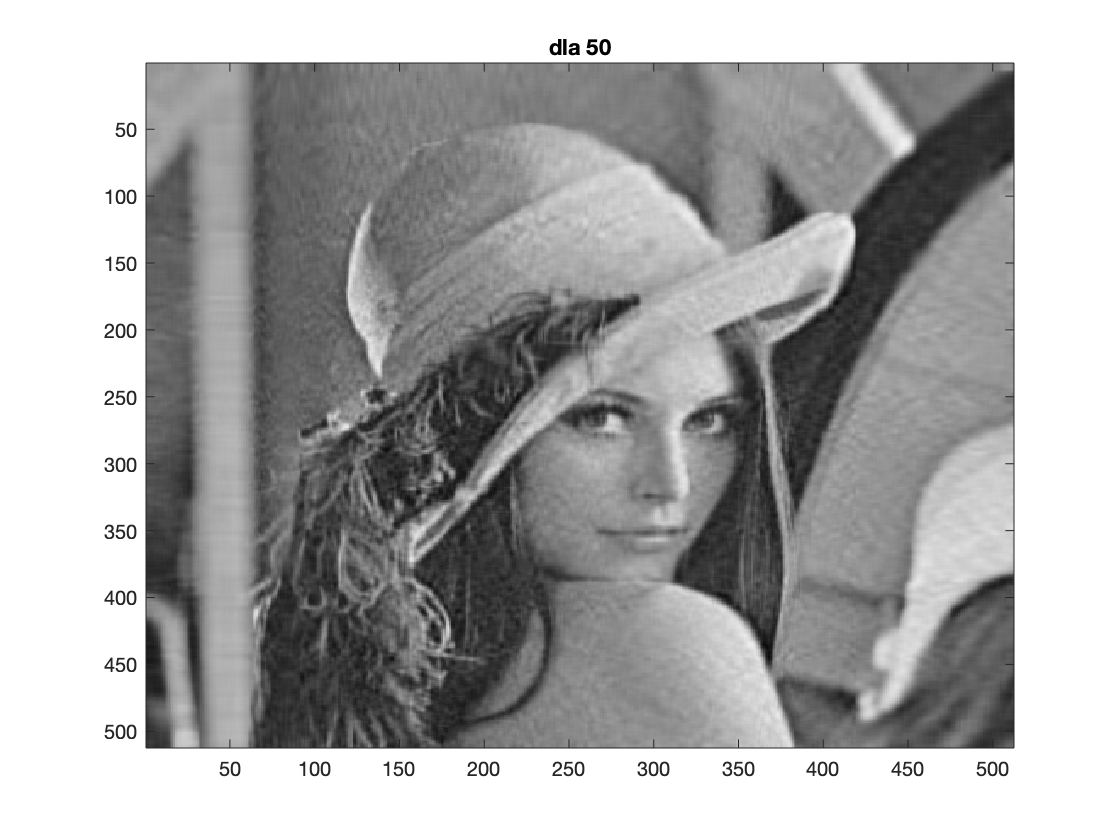

image(compressy{1})
colormap gray
title('dla 50')

dla 25:

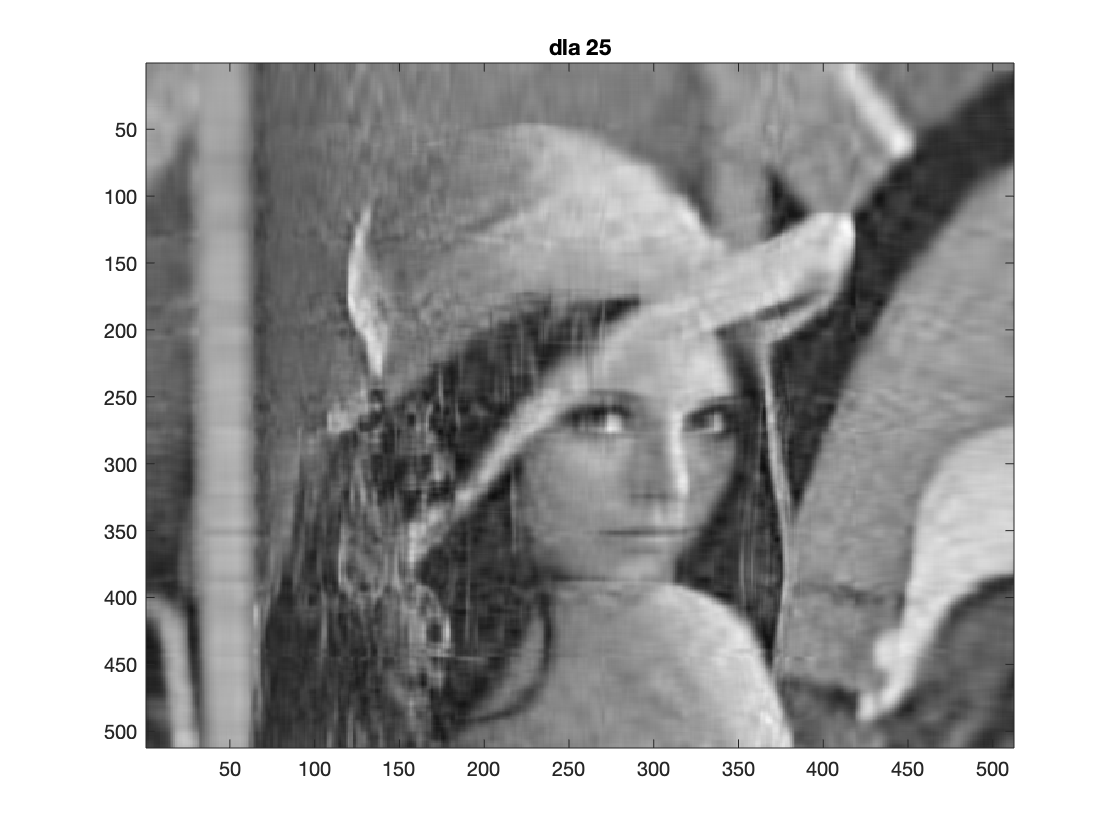

image(compressy{2})
colormap gray
title('dla 25')

dla 10:

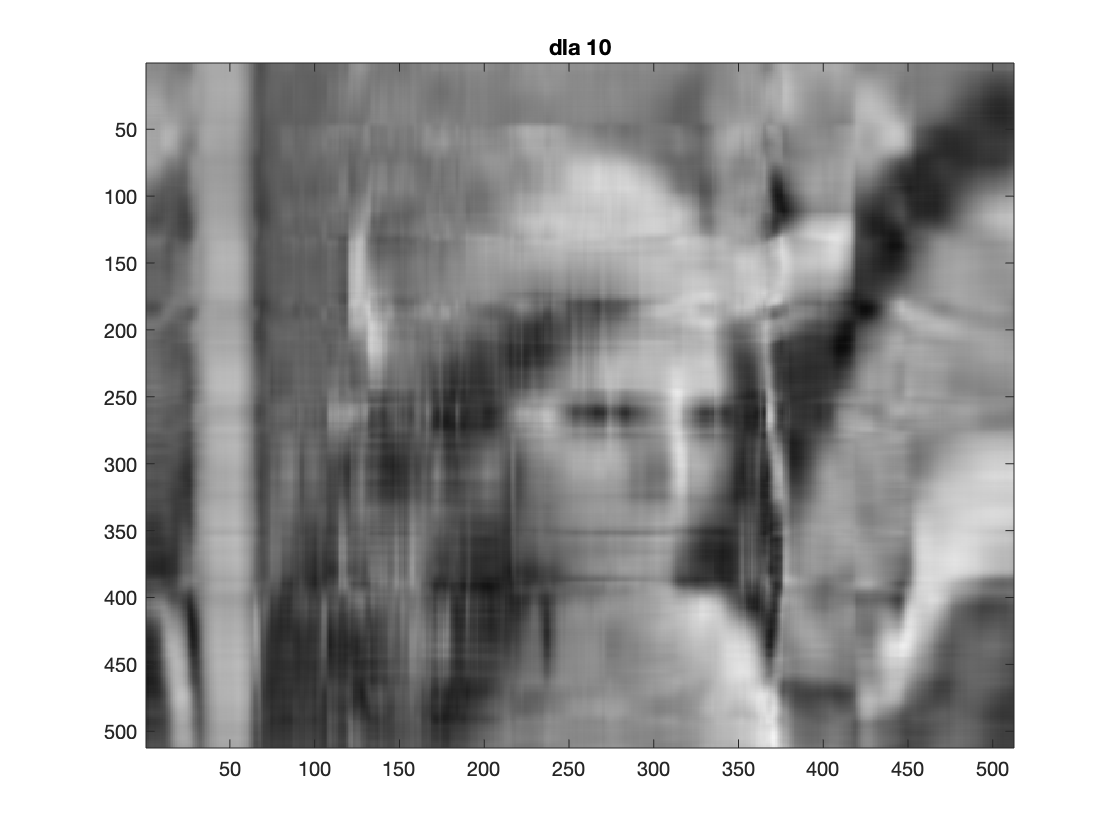

image(compressy{3})
colormap gray
title('dla 10')

dla 5:

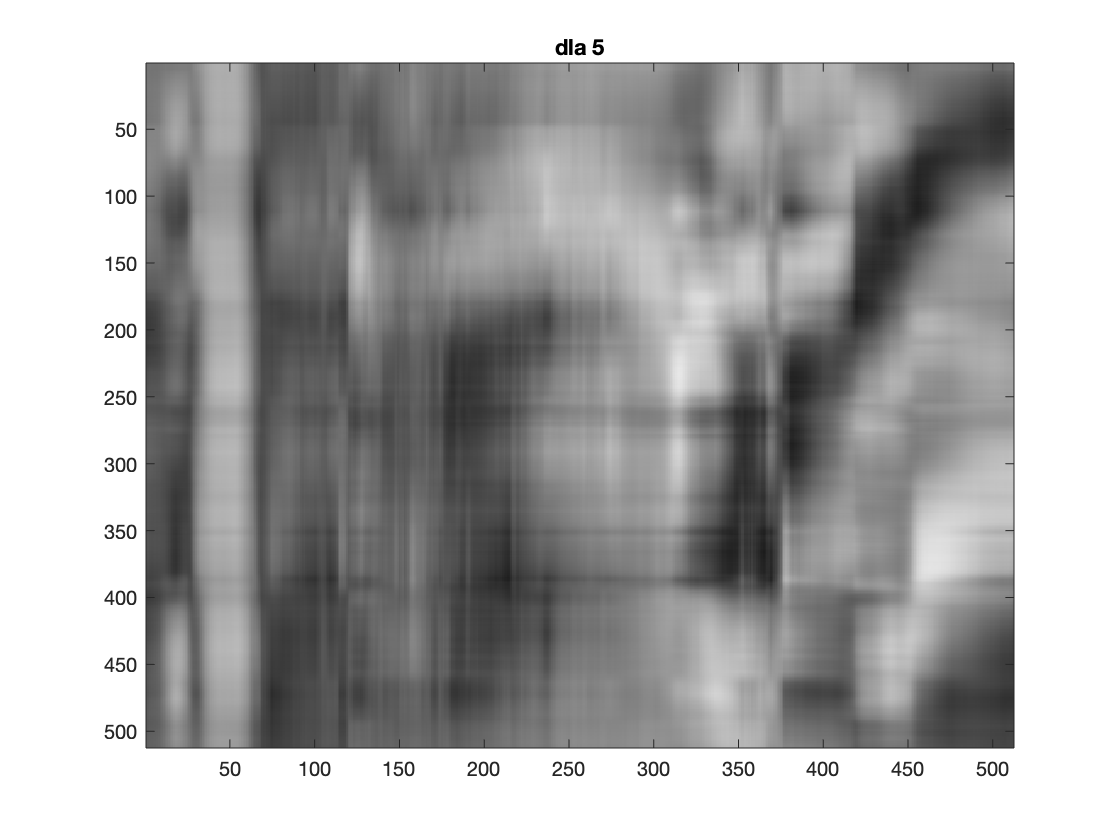

image(compressy{4})
colormap gray
title('dla 5')

dla 1:

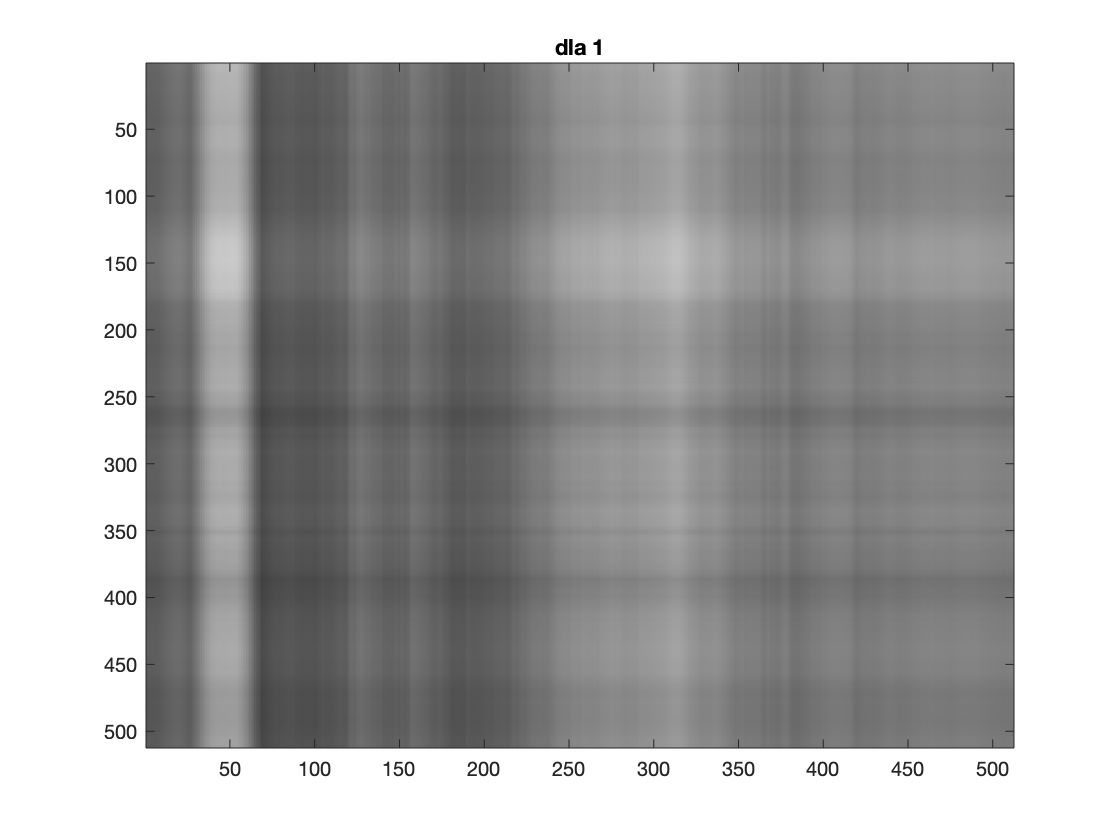

image(compressy{5})
colormap gray
title('dla 1')

poziomy podobienstwa:

for i=1:length(compressy)
    ssim(compressy{i},single(X))
end

ans = single
0.5254

ans = single
0.3870

ans = single
0.2574

ans = single
0.1662

ans = single
0.0755

poziomy szumow:

disp('========================================')

for i=1:length(compressy)
    PSNR(compressy{i},single(X))
end

ans = single
29.8278

ans = single
26.0076

ans = single
22.0687

ans = single
19.2313

ans = single
15.5000

## Kompresja obrazow przy uprzednim podzieleniu na bloki

TODO

podzial na bloki:

X_8 = mat2cell(single(X),512/8*ones(1,8),512/8*ones(1,8));

kompresja:

X_8post = {};
for i=1:size(X_8,1)
    for j=1:size(X_8,2)
        [U_8 S_8 V_8] = svd(single(X_8{i,j}));
        x_8post{i,j} = Compress(U_8, S_8, V_8, 50);
    end
end
% x_8post{i,j}
%[U_8,S_8,V_8] = svd(single(X_8));
% i1_8 = U_8*S_8*V_8';

w wyniku otrzymujemy

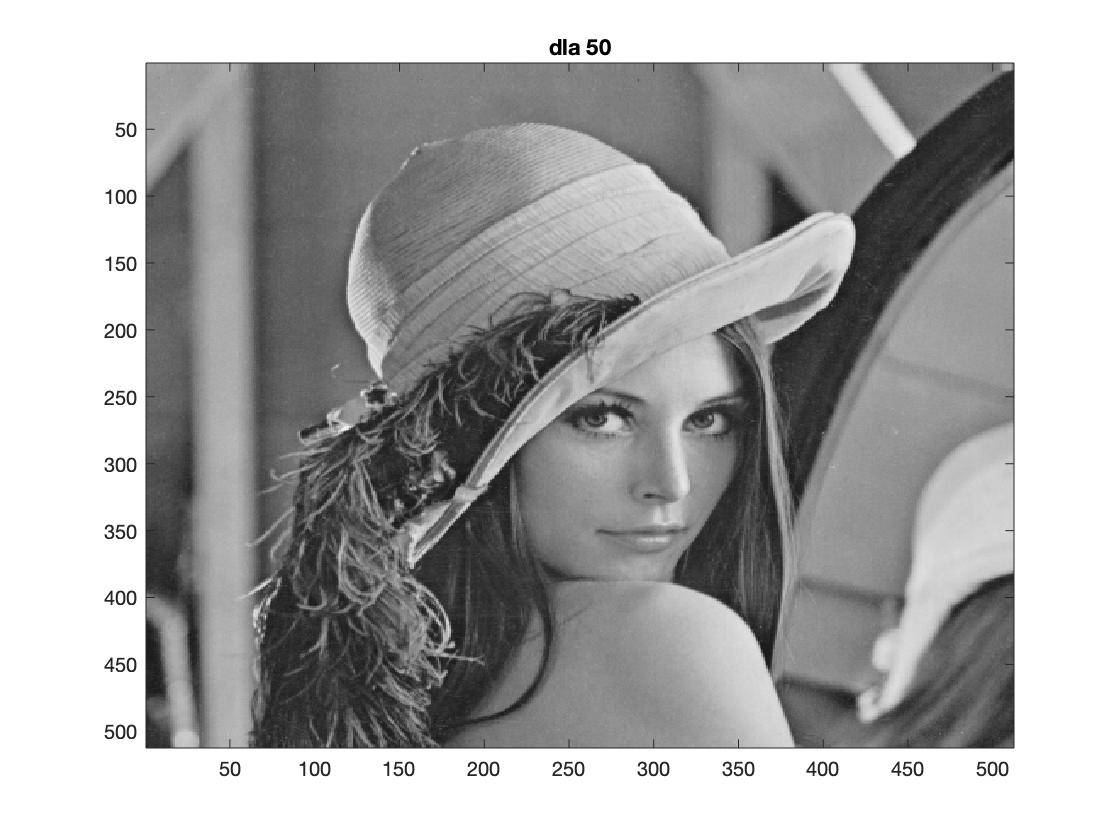

image(cell2mat(x_8post))
colormap gray
title('dla 50')

dla podzialu na 16x16

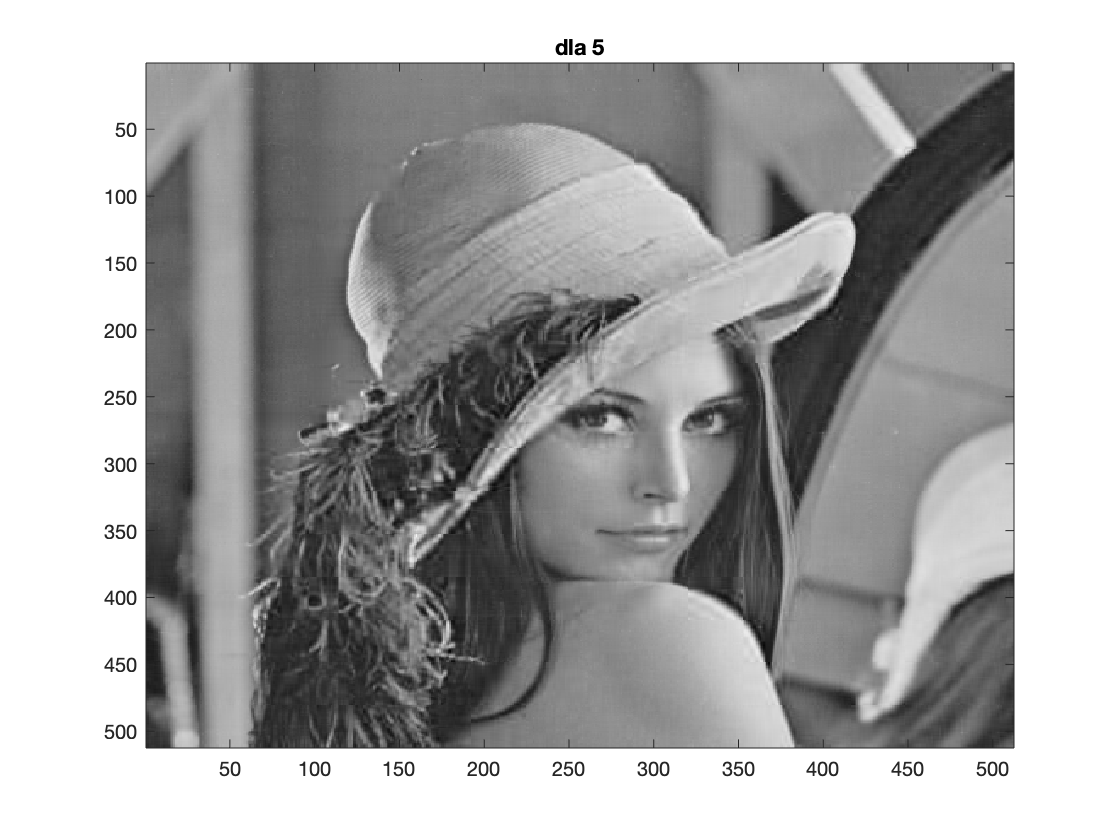

X_16 = mat2cell(single(X),512/16*ones(1,16),512/16*ones(1,16));

image(cell2mat(CommpresDodatkowy(X_16, 5)))
colormap gray
title('dla 5')


PSNR(cell2mat(CommpresDodatkowy(X_16, 5)), single(X))

ans = single
32.6527

function x_post = CommpresDodatkowy(x_mat, degree)
    x_post = {};
    for i=1:size(x_mat,1)
        for j=1:size(x_mat,2)
            [U_ S_ V_] = svd(single(x_mat{i,j}));
             x_post{i,j} = Compress(U_, S_, V_, degree);
      end
    end
end

funkcje

function im_post = Compress(U,S,V,comp)
    S_frag = zeros(size(S));
    S_frag(1:comp,1:comp) = S(1:comp,1:comp);
    im_post = U*S_frag*V';
end

PSNR function

function psnr = PSNR(comp, org)
    % obliczanie mse
    mse = 0;
    for i=1:size(org,1)
        for j=1:size(comp,1)
            mse = mse + (org(i,j)-comp(i,j))^2;
        end
    end
    mse = mse / (size(org,1) * size(comp,1));
    % obliczanie psnr
    psnr = 10*log10((max(org(:)))^2/mse);
end

funkcje do dodatkowego

function im_list = DivideIm(im, n)
    cell = size(im,1)/n;
    for i=1:n
        for j=1:n
            % im_list{i,j} = im(i*cell:(i+1)*cell, j*cell:(j+1)*cell ) 
        end
    end
end